%% Two-Edge-Resolved 3D NLOS Imaging (Supplementary Figure 6)
% Manuscript:
%   Czajkowski, R. and Murray-Bruce, J., 'Two-edge-resolved three-dimensional non-line-of-sight
% imaging with an ordinary camera', Nat. Commun., 2023.

% Author: Robinson Czajkowski

clear;
close all;

fun = HiddenScene;
indfun = @(x)(x>=0);
addpath("github_repo");


fit = 20000; % Figure Number
N = 256; % Pixels in length of image
h = 0.2; % Height of door head
snr = 79; % Signal to noise ratio of the observation image
image_size = 0.5; % Length of image

%Point Source at middle of scene
x = 0.5;
y = 0.5;
z = 0.5;

%Generate Cartesian observation coordinates
aa = linspace(0, 1, N+1);
aa = aa + 1/(2*N);
aa = aa(1:end-1);

bb = linspace(0, 1, N+1);
bb = bb + 1/(2*N);
bb = bb(1:end-1);
[AA, BB] = meshgrid(aa, bb);
a = AA(:);
b = BB(:);

a = a*image_size;
b = b*image_size;

f = 1/(2*N)*image_size;
rho = (x^2+y^2+z^2)^0.5;
theta = atan(y/x);
psi = atan(z/x);

phi = acos(z/rho);


% Calculate all relavent values for equations
[R, dR_dTheta, dR_dPsi, dR_dRho, H, H1, dH_dTheta, dH1_dTheta, dH_dPsi, SC, dC_dx, dC_dy, dC_dz] = compute_stuff(rho, theta, psi, a, b, f, h, N);


% Conversion Matrix to and from PESC Coordiante System

S = 1/(1+(tan(theta))^2+(tan(psi))^2)^(1/2);

Conversion_inverse = [-rho*tan(theta)*(sec(theta))^2*S^3 rho*(sec(theta))^2*S-rho*(tan(theta))^2*(sec(theta))^2*S^3 -rho*tan(theta)*tan(psi)*(sec(theta))^2*S^3          0;
                      -rho*tan(psi)*(sec(psi))^2*S^3     -rho*tan(theta)*tan(psi)*(sec(psi))^2*S^3                  rho*(sec(psi))^2*S-rho*(tan(psi))^2*(sec(psi))^2*S^3 0;
                      S                                  tan(theta)*S                                               tan(psi)*S                                           0;
                      0                                  0                                                          0                                                    1]';

Conversion = [1/(1+y^2/x^2)*(-y/x^2) 1/(1+z^2/x^2)*(-z/x^2)   x/(x^2+y^2+z^2)^0.5 0;
              1/(1+y^2/x^2)*(1/x)    0                        y/(x^2+y^2+z^2)^0.5 0;
              0                      1/(1+z^2/x^2)*(1/x)      z/(x^2+y^2+z^2)^0.5 0;
              0                      0                        0                   1]';

Conversion_c2s = [-rho*sin(theta)*sin(phi)   rho*cos(theta)*cos(phi) cos(theta)*sin(phi)    0;
                  rho*cos(theta)*sin(phi)    rho*sin(theta)*cos(phi) sin(theta)*sin(phi)    0;
                  0                          -rho*sin(phi)           cos(phi)               0;
                  0                          0                       0                      1]';



% Computes the sigma for each edge case. Must be different because the 
% same snr creates different sigma

sigma_0 = (10^(-0.1 * snr) * (sum(4*f^2*R(:))) / N)^0.5;
sigma_1 = (10^(-0.1 * snr) * (sum(H1(:).*R(:))) / N)^0.5;
sigma_2 = (10^(-0.1 * snr) * (sum(H(:).*R(:))) / N)^0.5;


"No Edges";

% CRB all variances
Delta_I = [4*f^2*dR_dTheta(:) 4*f^2*dR_dPsi(:) 4*f^2*dR_dRho(:) 4*f^2*R(:)];
Fisher = (1/sigma_0^2)*(Delta_I'*Delta_I);
CRB_sph0 = Fisher^-1;

Delta_I_Cart = Delta_I*Conversion;
Fisher_Cart = (1/sigma_0^2)*(Delta_I_Cart'*Delta_I_Cart);
CRB_cart0 = Fisher_Cart^-1;



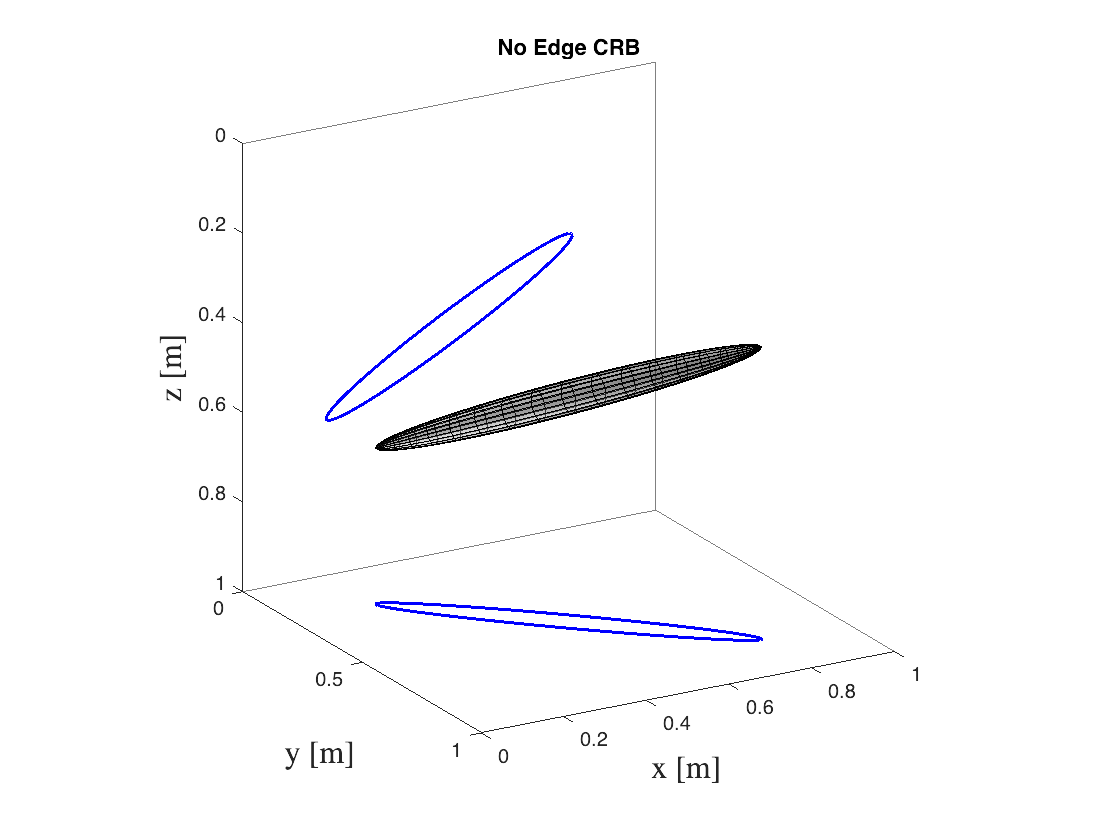

az = 60;
el = 20;
close all;

figure(101)
error_ellipse(CRB_cart0([2 1 3],[2 1 3]), [x, y, z], 'style', 'b')
xlim([-0 1])
ylim([-0 1])
zlim([0 1])
title("No Edge CRB")
xlabel('y [m]','Interpreter','latex','FontSize',16)
ylabel('x [m]','Interpreter','latex','FontSize',16)
zlabel('z [m]','Interpreter','latex','FontSize',16)
set(gca, 'Zdir', 'reverse')
hold on
plot3([0 1], [1 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [1 1], [0 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [0 0], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
axis square
view(az, el)
hold off

% saveas(figure(101),"CRB/0Edge");
% saveas(figure(101),"CRB/NoEdges.png");
%export_fig('CRB/NoEdge3D', '-pdf');


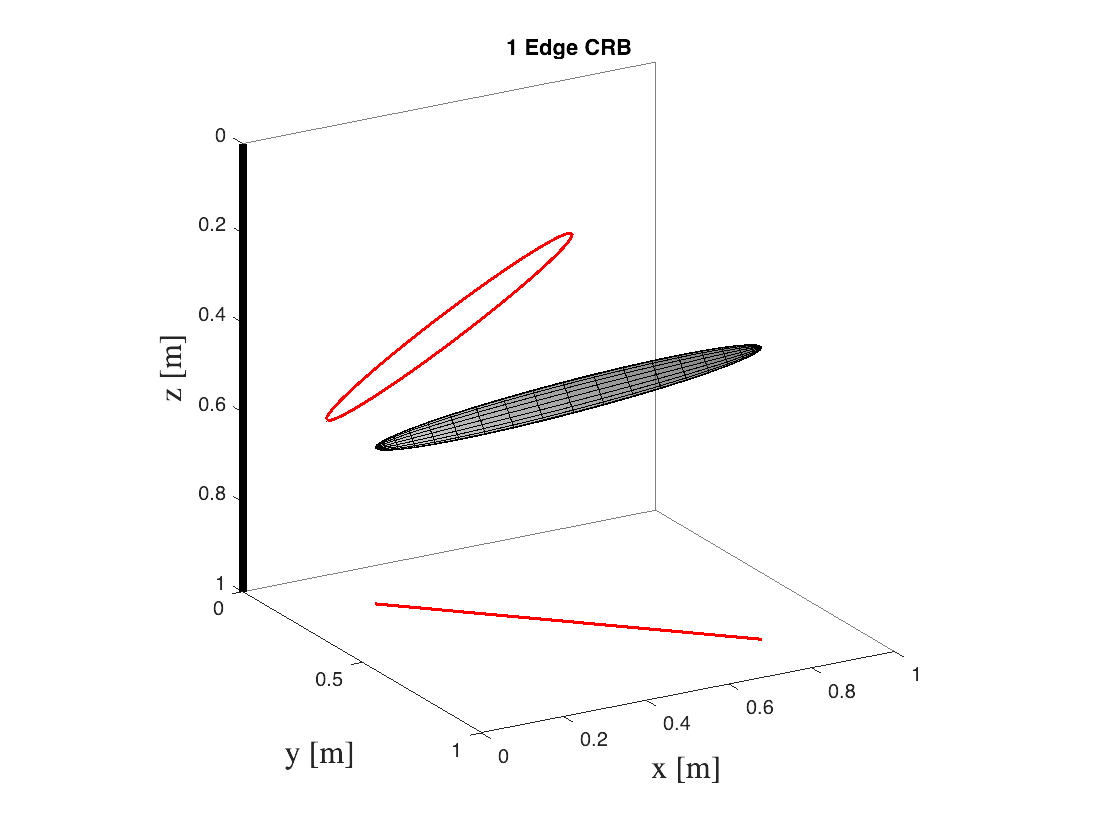

"One Edge";

% Multiplication Rule
M_t = R.*dH1_dTheta + H1.*dR_dTheta;
M_p = H1.*dR_dPsi;
M_r = dR_dRho.*H1;
M_c = R.*H1;

M_t = reshape(M_t, N, N);
M_p = reshape(M_p, N, N);
M_r = reshape(M_r, N, N);
M_c = reshape(M_c, N, N);

% CRB
Delta_I = [M_t(:) M_p(:) M_r(:) M_c(:)];
Fisher = (1/sigma_1^2)*(Delta_I'*Delta_I);
CRB_sph1 = Fisher^-1;

Delta_I_Cart = Delta_I*Conversion;
Fisher_Cart = (1/sigma_1^2)*(Delta_I_Cart'*Delta_I_Cart);
CRB_cart1 = Fisher_Cart^-1;


figure(102)
error_ellipse(CRB_cart1([2 1 3],[2 1 3]), [x, y, z], 'style', 'r')
xlim([-0 1])
ylim([-0 1])
zlim([0 1])
title("1 Edge CRB")
xlabel('y [m]','Interpreter','latex','FontSize',16)
ylabel('x [m]','Interpreter','latex','FontSize',16)
zlabel('z [m]','Interpreter','latex','FontSize',16)
set(gca, 'Zdir', 'reverse')
hold on
plot3([0 1], [1 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [1 1], [0 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [0 0], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 0], [0 1], 'k', 'LineWidth',4)
axis square
view(az, el)
hold off

% saveas(figure(102),"CRB/1Edge");
% saveas(figure(102),"CRB/1Edge.png");
%export_fig('CRB/OneEdge3D', '-pdf');

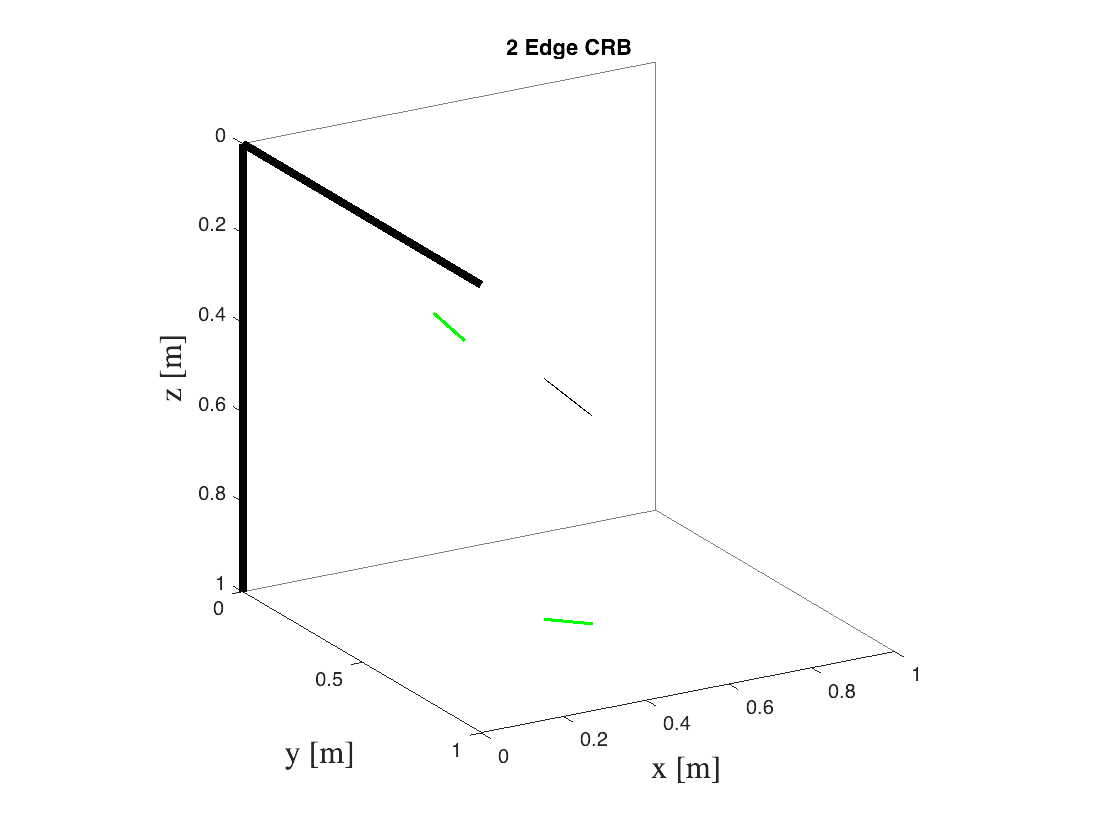

"Two Edges";
close all;

% Multiplication Rule
M_t = R.*dH_dTheta + H.*dR_dTheta;
M_p = R.*dH_dPsi + H.*dR_dPsi;
M_r = dR_dRho.*H;
M_c = R.*H;

M_t = reshape(M_t, N, N);
M_p = reshape(M_p, N, N);
M_r = reshape(M_r, N, N);
M_c = reshape(M_c, N, N);

% CRB
Delta_I = [M_t(:) M_p(:) M_r(:) M_c(:)];
Fisher = (1/sigma_2^2)*(Delta_I'*Delta_I);
CRB_sph2 = Fisher^-1;


Delta_I_Cart = Delta_I*Conversion;
Fisher_Cart = (1/sigma_2^2)*(Delta_I_Cart'*Delta_I_Cart);
CRB_cart2 = Fisher_Cart^-1;

figure(103)
error_ellipse(CRB_cart2([2 1 3],[2 1 3]), [x, y, z], 'style', 'g')

xlim([0 1])
ylim([0 1])
zlim([0 1])
title("2 Edge CRB")
%title("Completely Occluded Region")
xlabel('y [m]','Interpreter','latex','FontSize',16)
ylabel('x [m]','Interpreter','latex','FontSize',16)
zlabel('z [m]','Interpreter','latex','FontSize',16)
set(gca, 'Zdir', 'reverse')
hold on
plot3([0 1], [1 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [1 1], [0 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [0 0], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 1], [0 0], [0 0], 'k', 'LineWidth',4)
plot3([0 0], [0 0], [0 1], 'k', 'LineWidth',4)
axis square
view(az, el)

% saveas(figure(103),"CRB/2Edge");
% saveas(figure(103),"CRB/2Edge.png");
%export_fig('CRB/TwoEdge3D', '-pdf');


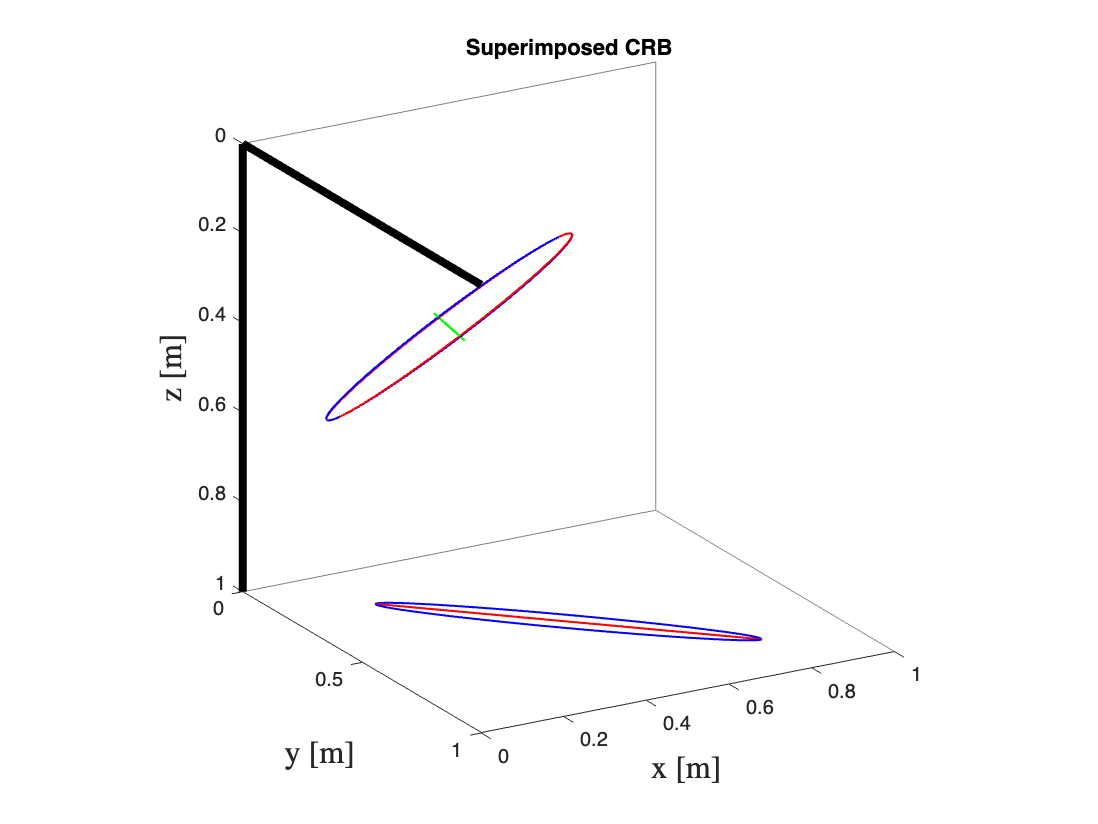

%Superimposed plots

figure(104)
error_ellipse_superimposed(CRB_cart0([2 1 3],[2 1 3]), [x, y, z], 'style', 'b')
xlim([-0 1])
ylim([-0 1])
zlim([0 1])
title("Superimposed CRB")
xlabel('y [m]','Interpreter','latex','FontSize',16)
ylabel('x [m]','Interpreter','latex','FontSize',16)
zlabel('z [m]','Interpreter','latex','FontSize',16)
set(gca, 'Zdir', 'reverse')
hold on
axis square
view(az, el)
hold on



error_ellipse_superimposed(CRB_cart1(1:3,1:3), [x, y, z], 'style', 'r')
hold on

error_ellipse_superimposed(CRB_cart2(1:3,1:3), [x, y, z], 'style', 'g')
plot3([0 1], [1 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [1 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [1 1], [0 1], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 0], [0 1], [0 0], 'color', [0.5 0.5 0.5], 'LineWidth',0.5)
plot3([0 1], [0 0], [0 0], 'k', 'LineWidth',4)
plot3([0 0], [0 0], [0 1], 'k', 'LineWidth',4)


% saveas(figure(104),"CRB/All3");
% saveas(figure(104),"CRB/All3.png");
%export_fig('CRB/AllYee', '-pdf');






function [R, dR_dTheta, dR_dPsi, dR_dRho, H, H1, dH_dTheta, dH1_dTheta, dH_dPsi, SC, dC_dx, dC_dy, dC_dz] = compute_stuff(rho, theta, psi, a, b, f, h, N)

    S = 1/(1+(tan(theta))^2+(tan(psi))^2)^(1/2);
    R = (rho^2 + 2*rho*(a*tan(theta)+b+h*tan(psi))*S + a.^2+b.^2+h^2).^-1;
    
    dR_dTheta = -R.^2 *2*rho .*( (S.*a.*(sec(theta))^2 - (b+a*tan(theta)+h*tan(psi))*tan(theta)*(sec(theta))^2*S^3) );
    dR_dPsi =   -R.^2 *2*rho .*( (S.*h.*(sec(psi))^2   - (b+a*tan(theta)+h*tan(psi))*tan(psi)*(sec(psi))^2*S^3) );
    dR_dRho =   -R.^2 .* (2*rho + 2*(a*tan(theta)+b+h*(tan(psi)))*S);
    
    % Create cartesian directly
    x = rho.*S;
    y = tan(theta).*x;
    z = tan(psi).*x;
    
    SC = ((x+b).^2 + (y+a).^2 + (z+h).^2).^(-1);
    dC_dx = -2*(x+b).*SC.^2;
    dC_dy = -2*(y+a).*SC.^2;
    dC_dz = -2*(z+h).*SC.^2;
    
    
    H = 1/2 * (max(min(b+f,(a+f)*cot(theta)),max(b-f,h*cot(psi)))).^2 * tan(theta) - max(min(b+f,(a+f)*cot(theta)),max(b-f,h*cot(psi))).*(a-f) ...
        - 1/2 * (max(b-f, max(h*cot(psi), (a-f)*cot(theta)))).^2 * tan(theta) ...
        + max(b-f, max(h*cot(psi), (a-f)*cot(theta))).*(a-f) + 2*f*(b+f) ...
        - 2*f*max(min(b+f,(a+f)*cot(theta)),max(b-f,h*cot(psi)));
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        
        if h*cot(psi) > b0+f || (a0-f)*cot(theta) > b0+f
            H(i) = 0;
        end
    end
    
    H1 = 1/2 * (max(min(b+f,(a+f)*cot(theta)),b-f)).^2 * tan(theta) - max(min(b+f,(a+f)*cot(theta)),b-f).*(a-f) ...
        - 1/2 * (max(b-f, (a-f)*cot(theta))).^2 * tan(theta) ...
        + max(b-f, (a-f)*cot(theta)).*(a-f) + 2*f*(b+f) ...
        - 2*f*max(min(b+f,(a+f)*cot(theta)),b-f);
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        
        if (a0-f)*cot(theta) > b0+f
            H1(i) = 0;
        end
    end
    
    dH_dTheta = zeros(1,N^2);
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        
        if (a0+f)*cot(theta) <= b0-f || (a0-f)*cot(theta) >= b0+f || h*cot(psi) >= b0+f || h*cot(psi) > (a0+f)*cot(psi)
            dH_dTheta(i) = 0;
            continue
        end
        
        if b0+f > (a0+f)*cot(theta)
            if (a0-f)*cot(theta) > max(b0-f,h*cot(psi))
                dH_dTheta(i) = 0.5*(a0+f)^2*(csc(theta))^2 - 0.5*(a0-f)^2*(csc(theta))^2;
            else
                dH_dTheta(i) = 0.5*(a0+f)^2*(csc(theta))^2 - 0.5*(max(b0-f,h*cot(psi)))^2*(sec(theta))^2;
            end
        else
            if (a0-f)*cot(theta) > max(b0-f,h*cot(psi))
                dH_dTheta(i) = 0.5*(b0+f)^2*(sec(theta))^2 - 0.5*(a0-f)^2*(csc(theta))^2;
            else
                dH_dTheta(i) = 0.5*(b0+f)^2*(sec(theta))^2 - 0.5*(max(b0-f,h*cot(psi)))^2*(sec(theta))^2;
            end
        end
    end
    
    dH_dTheta = -(1/2)*(min(b+f,(a+f)*cot(theta))).^2 *(sec(theta))^2+(1/2)*(max(max(b-f,h*cot(psi)),(a-f)*cot(theta))).^2 *(sec(theta))^2;
    dH_dTheta = (1/2)*(sec(theta))^2 * ( (max(max(b-f,h*cot(psi)),(a-f)*cot(theta))).^2 - (min(max(b+f,h*cot(psi)),(a+f)*cot(theta))).^2  );
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        if (a0+f)*cot(theta) <= max(b0-f,h*cot(psi)) || (a0-f)*cot(theta) >= max(b0+f,h*cot(psi))
            dH_dTheta(i) = 0;
        end
    end
    
    dH1_dTheta = zeros(1,N^2);
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        
        if (a0+f)*cot(theta) <= b0-f || (a0-f)*cot(theta) >= b0+f
            dH1_dTheta(i) = 0;
            continue
        end
        
        if b0+f > (a0+f)*cot(theta)
            if (a0-f)*cot(theta) > b0-f
                dH1_dTheta(i) = 0.5*(a0+f)^2*(csc(theta))^2 - 0.5*(a0-f)^2*(csc(theta))^2;
            else
                dH1_dTheta(i) = 0.5*(a0+f)^2*(csc(theta))^2 - 0.5*(b0-f)^2*(sec(theta))^2;
            end
        else
            if (a0-f)*cot(theta) > b0-f
                dH1_dTheta(i) = 0.5*(b0+f)^2*(sec(theta))^2 - 0.5*(a0-f)^2*(csc(theta))^2;
            else
                dH1_dTheta(i) = 0.5*(b0+f)^2*(sec(theta))^2 - 0.5*(b0-f)^2*(sec(theta))^2;
            end
        end
    end
    
    dH_dPsi = h*(csc(psi))^2 * (min(a-f, h*cot(psi)*tan(theta)) - min(a+f, h*cot(psi)*tan(theta)));
    for i=1:length(a(:))
        a0 = a(i);
        b0 = b(i);
        
        if b0-f > h*cot(psi) || h*cot(psi) > b0+f
            dH_dPsi(i) = 0;
        end
    end
    
    
    R = reshape(R, N, N);
    dR_dTheta = reshape(dR_dTheta, N, N);
    dR_dPsi = reshape(dR_dPsi, N, N);
    dR_dRho = reshape(dR_dRho, N, N);
    H = reshape(H, N, N);
    H1 = reshape(H1, N, N);
    dH_dTheta = reshape(dH_dTheta, N, N);
    dH1_dTheta = reshape(dH1_dTheta, N, N);
    dH_dPsi = reshape(dH_dPsi, N, N);
    
    SC = reshape(SC,N,N);
    dC_dx = reshape(dC_dx,N,N);
    dC_dy = reshape(dC_dy,N,N);
    dC_dz = reshape(dC_dz,N,N);
end